# **Visión Artificial. GIEC-GITT.**

# **Sistemas de Visión Artificial. GII-GIC-GISI.**

** Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel**

** Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Paula Fernández Sánchez, Luis Ramos Triguero, María Díez Martínez**

**Fecha: 17/11/2026**

# Tema 4. Ejercicio 5. Texturas

El objetivo de este ejercicio es la caracterización de texturas. Para ello, sobre imágenes con texturas diferentes, se obtendrán y compararán los valores de entropía, las matrices de coocurrencia en niveles de gris (GLCM) y diferentes estadísticas obtenidas a partir de las GLCM para diversos vectores de desplazamiento (*offset)*.

Paso 1) Lectura de las imágenes.

clear all
close all
% textures from http://www.cb.uu.se/~gustaf/texture/
imagenames = {'texture-stone.png','texture-sand.png','texture-linseeds.png', ...
              'texture-canvas.png','texture-pattern1.png','texture-pattern2.png'};

textureImg=[];
for n=1:length(imagenames)
    textureImg{n} = imread(imagenames{n});
end

Paso 2) **Entropía:** Calcule la entropía de las imágenes de patrones *textureImg* leídas en el paso anterior (usando la función `entropy)`, y ordénelas (usando la función `sort)`, en orden creciente de entropía (de la más baja a la más alta) y muestre las imágenes y su entropía según dicho orden. ¿Qué imagen tiene la menor entropía? Relacione el resultado con la distribución de sus niveles de gris y justifique sus conclusiones.

JUSTIFICACIONES: La de menor entropía es pattern2 (≈4.2), y el orden de menor a mayor es pattern2, pattern1, canvas, sand, stone y linseeds (≈7.3). Pattern2 casi solo tiene dos niveles de gris, el fondo gris y los círculos blancos, así que su histograma está muy concentrado y la imagen es muy predecible. Linseeds tiene los niveles de gris muy repartidos, y por eso su entropía es la más alta.

E = zeros(1,length(imagenames));
for n=1:length(imagenames)
    E(n) = entropy(textureImg{n});
end
[Eord, idx] = sort(E)

Eord =     4.1983    4.7936    5.9055    6.5980    6.8046    7.2660


idx =      6     5     4     2     1     3


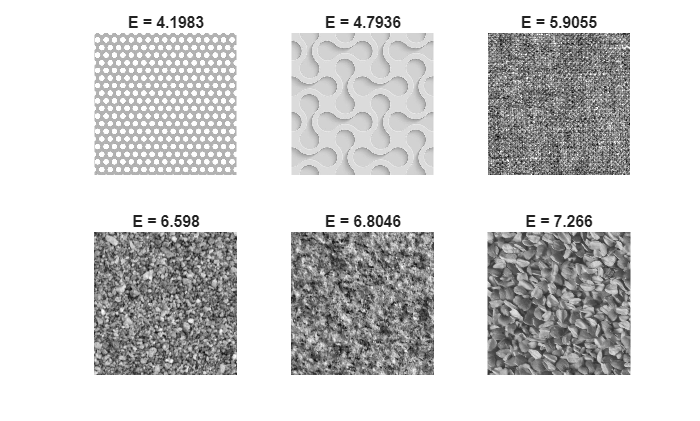

figure
for n=1:length(imagenames)
    subplot(2,3,n)
    imshow(textureImg{idx(n)})
    title(['E = ' num2str(Eord(n))])
end

Paso 3) **GLCM (Matriz de coocurrencia de niveles de gris). **Lea la ayuda de la función `graycomatrix` para entender todos sus parámetros ([https://es.mathworks.com/help/images/ref/graycomatrix.html](https://es.mathworks.com/help/images/ref/graycomatrix.html)). Defina los vectores de desplazamiento (`offsets`) correspondientes a las direcciones 0°, 45°, 90° y 135°, utilizando `len=5`. Utilícelos para calcular el conjunto de matrices de coocurrencia (GLCMs), usando la función `graycomatrix` sobre los ficheros anteriores. Puede serle útil consultar el código del ejemplo "**Calcular GLCM utilizando cuatro desfases diferentes" **de la ayuda de la función `graycomatrix`. Compruebe en la ayuda qué número de niveles de gris utiliza `graycomatrix` por defecto y relacione este comportamiento con lo estudiado en teoría.

JUSTIFICACION: Por defecto `graycomatrix` usa 8 niveles de gris, así que cada GLCM es de 8×8 en vez de 256×256. El tamaño de la matriz depende del número de niveles de gris, y si son muchos se cuantifica la imagen para que la matriz sea manejable.

len = 5;
% [row_offset, col_offset]
offsets = [0 len;
    -len len;
    -len 0;
    -len -len];
%co-ocurrence matrix
glcm = [];
for n=1:length(imagenames)
    glcm{n} = graycomatrix(textureImg{n},'Offset',offsets);
end

Paso 4) Visualice la primera GLCM, correspondiente al primer offset, utilizando colores escalados. Observe cómo se distribuyen sus valores y compárela con las GLCM correspondientes a otros vectores de desplazamiento. Para ello puede adaptar el código siguiente:

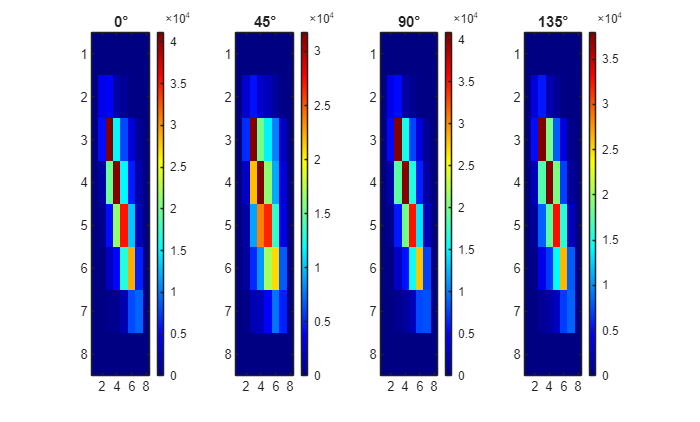

angulos = {'0°','45°','90°','135°'};
n = 3;
figure
for k = 1:4
    subplot(1,4,k)
    imagesc(glcm{n}(:,:,k))
    colormap jet
    colorbar
    title(angulos{k})
end

Paso 5) Obtenga y visualice los estadísticos  `Contrast, Correlation, Energy y Homogeneity` de las GLCM utilizando la función `graycoprops` para las imágenes `'texture-linseeds.png'` y `'texture-pattern2.png'` utilizando las GLCM correspondientes a los diferentes vectores de desplazamiento definidos anteriormente.

Compare los valores obtenidos para las dos texturas y para los diferentes offsets. ¿Qué propiedades cambian al modificar la dirección del desplazamiento? Relacione los resultados con las características visuales de las dos texturas.

JUSTIFICACION: Al cambiar la dirección, lo que más varía es el contrast y la correlation. A 45° y 135° el contraste sube y la correlación baja, porque los píxeles comparados están más lejos y se parecen menos. Energy y homogeneity cambian poco. Linseeds tiene más contraste y menos energía porque es una textura irregular con muchos niveles de gris. Pattern2 tiene mucha más energía y homogeneidad porque es un patrón regular de casi dos niveles, y por eso sus valores a 0° y 90° salen iguales, igual que a 45° y 135°.

stats3 = graycoprops(glcm{3})

stats3 = struct with fields:
       Contrast: [1.1175 1.8643 1.1435 1.2652]
    Correlation: [0.6620 0.4365 0.6543 0.6175]
         Energy: [0.0707 0.0553 0.0694 0.0650]
    Homogeneity: [0.7177 0.6353 0.7126 0.6947]


stats6 = graycoprops(glcm{6})

stats6 = struct with fields:
       Contrast: [0.7854 1.1304 0.7914 1.1299]
    Correlation: [0.5673 0.3774 0.5641 0.3777]
         Energy: [0.3233 0.2815 0.3230 0.2815]
    Homogeneity: [0.8446 0.7875 0.8441 0.7876]


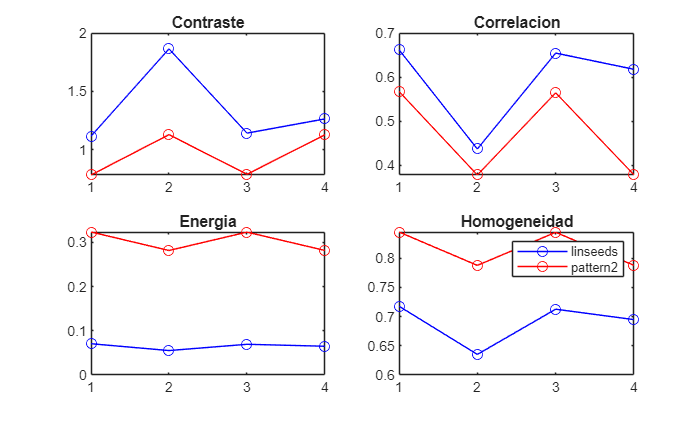


figure
subplot(2,2,1)
plot(stats3.Contrast,'b-o')
hold on
plot(stats6.Contrast,'r-o')
title('Contraste')
subplot(2,2,2)
plot(stats3.Correlation,'b-o')
hold on
plot(stats6.Correlation,'r-o')
title('Correlacion')
subplot(2,2,3)
plot(stats3.Energy,'b-o')
hold on
plot(stats6.Energy,'r-o')
title('Energia')
subplot(2,2,4)
plot(stats3.Homogeneity,'b-o')
hold on
plot(stats6.Homogeneity,'r-o')
title('Homogeneidad')
legend('linseeds','pattern2')